clc; clear all; close all;
% This is Circuit number 22 . R1 = 1400 Ohm , R2 = 2200 Ohm , R3 = 1800 Ohm , C1 = 13 microFarad , C2 = 14 microFarad , diode minimum resistance RD1 = 1 Ohm , diode minimum resistance RD2 = 1 Ohm , rms supply V1 = 150 Volt , supply frequency f1 = 50 Hz , rms supply V2 = 90 Volt , supply frequency f2 = 50 Hz , C1 initial voltage = 0 Volt , C2 initial voltage = 0 Volt , simulation time = 0.08 Seconds . What is the rms value of the current [milliAmpere] in resistor R2 ?

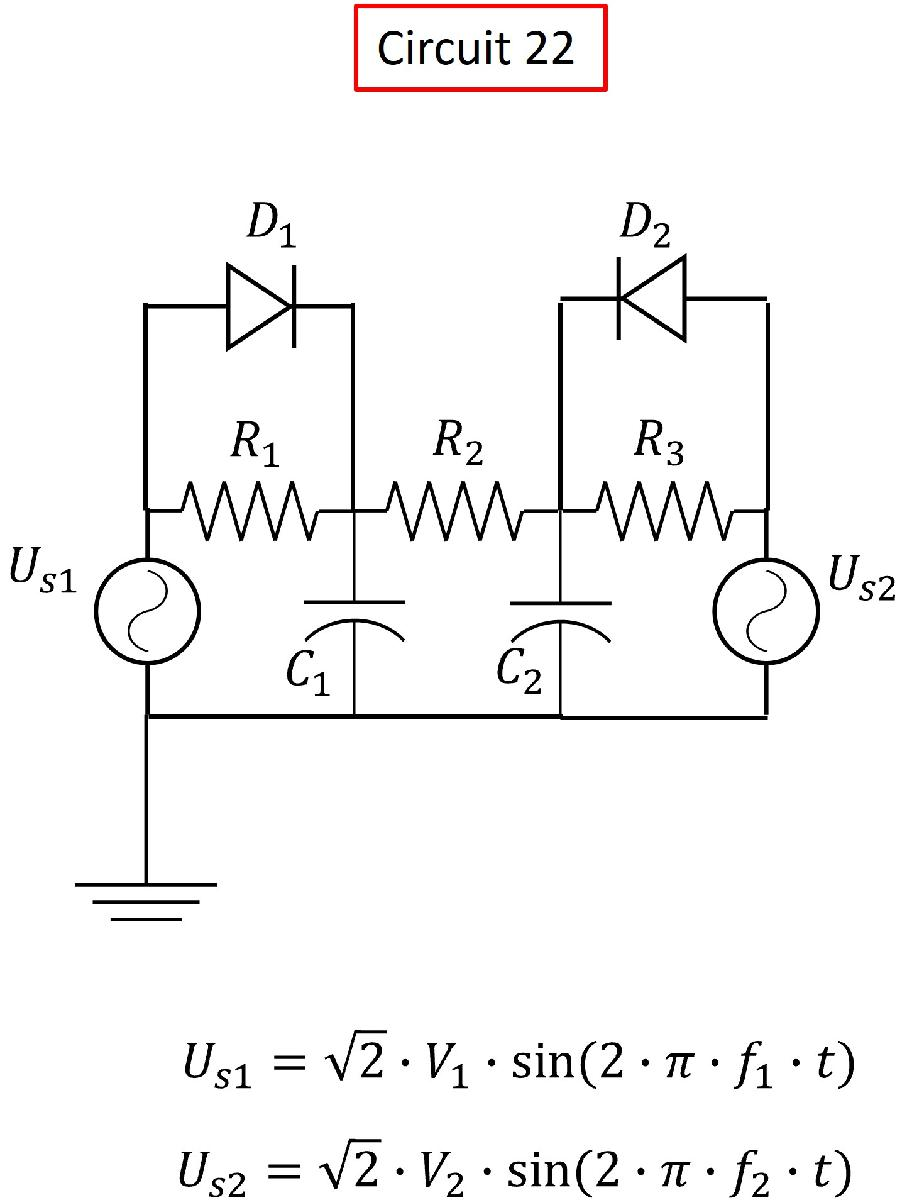

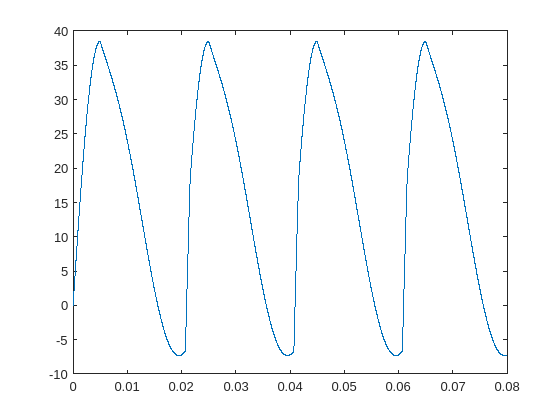

R1 = 1400; % Ohm
R2 = 2200; % Ohm
R3 = 1800; % Ohm

C1 = 13*10^-6; % F
C2 = 14*10^-6; % F

RD1 = 1; % Ohm
RD2 = 1; % Ohm

V1 = 150; % V rms
f1 = 50; % Hz

V2 = 90; % V rms
f2 = 50; % Hz

UC1 = 0; % V
UC2 = 0; % V

simTime = 0.08; % s
t = 0; % s
dt = 10^-5; % s
idx = 1;

while(t <= simTime)
    % Calculation

    Us1 = sqrt(2)*V1*sin(2*pi*f1*t);
    Us2 = sqrt(2)*V2*sin(2*pi*f2*t);
    i1 = (Us1-UC1)/R1;
    i2 = (UC1-UC2)/R2;
    i3 = (UC2-Us2)/R3;
    if(Us1 > UC1)
        i6 = (Us1-UC1)/RD1;
    elseif(Us1<=UC1)
        i6 = 0;
    end

    if(Us2 > UC2)
        i7 = (Us2-UC2)/RD2;
    elseif(Us2 <= UC2)
        i7 = 0;
    end
    i4 = i1+i6-i2;
    i5 = i2-i3+i7;

    UC1Dot = 1/C1 * i4;
    UC2Dot = 1/C2 * i5;

    % Logging
    t_plt(idx) =  t;
    i2_plt(idx) = i2*1000;
    % Time integration
    UC1 = UC1 + UC1Dot * dt;
    UC2 = UC2 + UC2Dot * dt;

    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, i2_plt)

i2rms = rms(i2_plt)

i2rms =           22.3938177117467



disp(" What is the rms value of the current [milliAmpere] in resistor R2 ?")

 What is the rms value of the current [milliAmpere] in resistor R2 ?
